clearvars;
addpath("helperFunctions/");

# Least Square Method

### Initial Parameters

n = 3; spacing = 0.01;
f = 200; c = 343; omega = 2*pi*f;
rho_k = omega/c;
S = my_sph2cart(deg2rad(90),deg2rad(405),2);
mag = 10;
[rho_s,the_s,phi_s] = my_cart2sph(S);
rx = -n:spacing:n;
ry = rx;
sz = [length(ry) length(rx)];
rz = zeros(size(rx));
r = [rx;ry;rz];
R = 0.5; % region of interrest
L = ceil(exp(1)*rho_k*R/2);
N = L-1;

### Monopole Wave

wave = monopoleWave(S,r,mag,rho_k,0);

### Microphone Array

waveFun = @(R,the,phi) monopoleWaveSpherical(mag,rho_s,the_s,phi_s,R,the,phi,rho_k);
[Blm,mic] = harmonicCoefficients(L,R,rho_k,N,waveFun,n,wave,0);
B = Blm(1,1);
for idl=2:(L+1)
    l=idl-1;
    for idm=1:(2*l+1)
        B = [B Blm(idl,idm)];
    end
end
B = B.';

### Loudspeaker

[nlspkr,lspkr] = loudspeaker_positions(n,1);

### 3D Plot

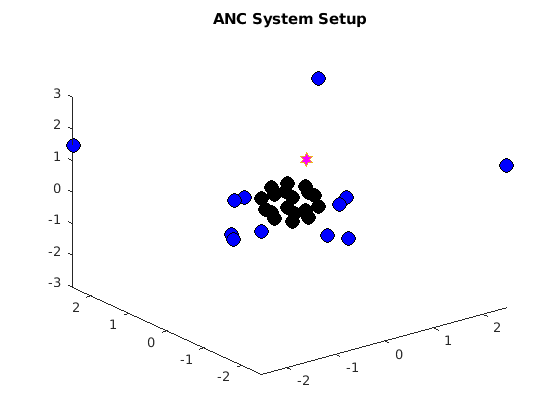

setupPlot(wave,mic,lspkr,S,R,n,spacing,3,0);

### 2D Plot with wave

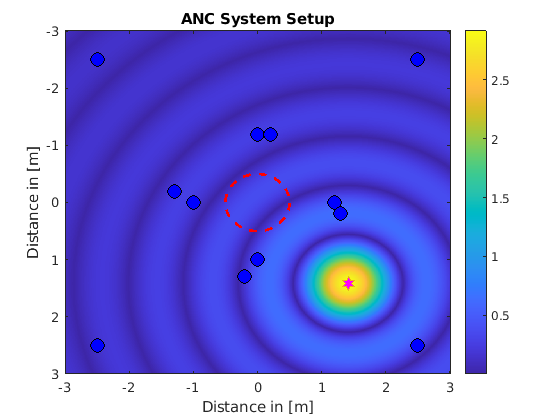

setupPlot(wave,mic,lspkr,S,R,n,spacing,2,1);

### Loudspeaker Coefficients

Nulm = zeros(L+1,2*L+1,nlspkr);
for i = 1:size(lspkr,2)
    [rho_i,the_i,phi_i] = my_cart2sph(lspkr(:,i));
    waveFun = @(R,the,phi) monopoleWaveSpherical(mag,rho_i,the_i,phi_i,R,the,phi,rho_k);
    [Nulm(:,:,i),~] = harmonicCoefficients(L,R,rho_k,N,waveFun,n,wave,0);
end


Nu = zeros(size(B,1),size(lspkr,2));
for i = 1:nlspkr
    id = 1;
    for idl=1:(L+1)
        l = idl-1;
        for idm=1:(2*l+1)
            Nu(id,i) = Nulm(idl,idm,i);
            id = id+1;
        end
    end
end

### Louspeaker Driving Signal

d = -pinv(Nu)*B;

###  Secondary Sound Field

s_xk = zeros(sz(1),sz(2),nlspkr);

for i=1:nlspkr
    [rho_i,the_i,phi_i] = my_cart2sph(lspkr(:,i));
    for idy = 1:sz(1)
        for idx = 1:sz(2)
            [rho,the,phi] = my_cart2sph([rx(idx);ry(idy);0]);
            G = monopoleWaveSpherical(mag,rho_i,the_i,phi_i,rho,the,phi,rho_k);
            s_xk(idy,idx,i) = G*d(i);
        end
    end
     
end

### Residual Noise Field

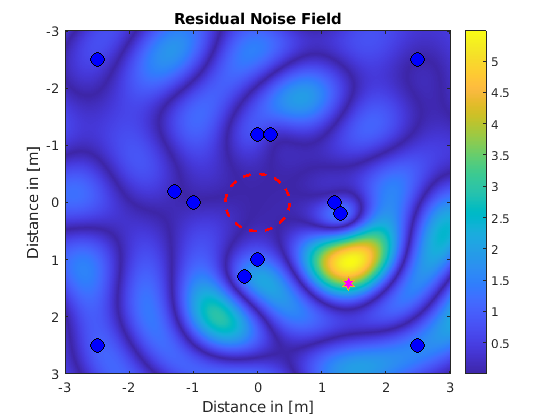

e = wave;
for i=1:nlspkr
    e = e+s_xk(:,:,i);
end
figure;
setupPlot(e,mic,lspkr,S,R,n,spacing,2,1);
title("Residual Noise Field")

%setupPlot((e-wave),mic,lspkr,n,1);
